%clearing the output window
clc;
close all;

% initializing the system states
x_initial = [0;0;10;0;30;0;0;0;0;0;0;0]

x_initial =      0
     0
    10
     0
    30
     0
     0
     0
     0
     0


% defining the time axis and sampling
timespan=0:0.1:100;
[t,x] = ode45(@twoload_lqg,timespan,x_initial);
%plotting the graph
disp("The graph is plotted below :")

The graph is plotted below :


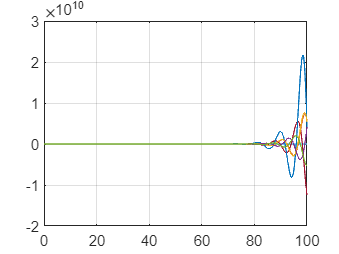

plot(t,x)
grid on

% Inbuit matlab Function twoload_lqg for non linear LQG control

function ydot = twoload_lqg(t,y)
% initializing the variables with values given in the question
M=1000; 
m1=100;
m2=100;
l1=20;
l2=10;
g=9.81;
% Matrix A is:
A=[0 1 0 0 0 0; 
    0 0 -(m1*g)/M 0 -(m2*g)/M 0;
    0 0 0 1 0 0;
    0 0 -((M+m1)*g)/(M*l1) 0 -(m2*g)/(M*l1) 0;
    0 0 0 0 0 1;
    0 0 -(m1*g)/(M*l2) 0 -(g*(M+m2))/(M*l2) 0];
B=[0; 1/M; 0; 1/(M*l1); 0; 1/(M*l2)];
Q=[100 0 0 0 0 0;
   0 100 0 0 0 0;
   0 0 100 0 0 0;
   0 0 0 100 0 0;
   0 0 0 0 100 0;
   0 0 0 0 0 100];
R=0.01;

% From the previous calculations, we know that only C1, C3 and C4 were
% observable. Hence, we are considering C1 in the below step here.
C1_matrix = [1 0 0 0 0 0];  %Corresponding to x component

D_matrix = 0;
K_val = lqr(A,B,Q,R);
F=-K_val*y(1:6);

vd=0.3*eye(6);
vn=1;
K_pop=lqr(A',C1_matrix',vd,vn)';

sd =(A-K_pop*C1_matrix)*y(7:12);

ydot=zeros(12,1);
% y(1)=x; y(2)=xdot; y(3)=theta1;   y(4)=theta1_dot;  
% y(5)=theta2;    y(6)=theta2_dot;
ydot(1) = y(2);%XD;
ydot(2)=(F-(g/2)*(m1*sind(2*y(3))+m2*sind(2*y(5)))-(m1*l1*(y(4)^2)*sind(y(3)))-(m2*l2*(y(6)^2)*sind(y(5))))/(M+m1*((sind(y(3)))^2)+m2*((sind(y(5)))^2));%xDD
ydot(3)= y(4);%theta1D;
ydot(4)= (ydot(2)*cosd(y(3))-g*(sind(y(3))))/l1';%theta1 Ddot;
ydot(5)= y(6);%theta2D
ydot(6)= (ydot(2)*cosd(y(5))-g*(sind(y(5))))/l2;%theta2 Ddot;
ydot(7)= y(2)-y(10); 
ydot(8)= ydot(2)-sd(2);
ydot(9)= y(4)-y(11);
ydot(10)= ydot(4)-sd(4);
ydot(11)= y(6)-y(12);
ydot(12)= ydot(6)-sd(6);
end
